Paso 1 

Aplicar una entrada tipo escalon al proceso en lazo abierto.

num = [0.25];
den = [1, 0.9, 0.25];%<-- Aquí modifiqué zeta intencionalmente
G = tf(num, den)


G =
 
         0.25
  ------------------
  s^2 + 0.9 s + 0.25
 
Continuous-time transfer function.
Model Properties


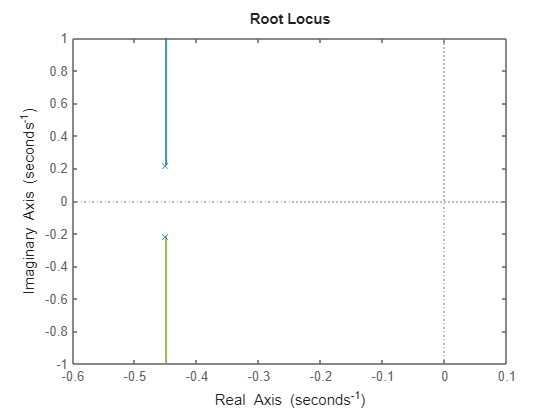

figure;
rlocus(G)

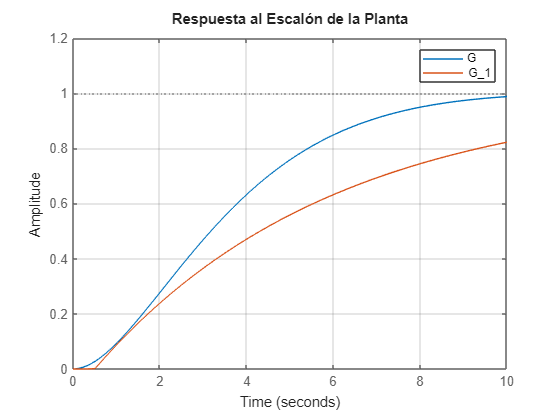

figure;
step(G);
xlim([0, 10]);

title('Respuesta al Escalón de la Planta');
grid on;
hold on
num = 1;          
den = [5.5 1];      
ioDelay = 0.5;     
G_1 = tf(num, den, 'InputDelay', ioDelay);
step(G_1)
legend('G','G_1')
hold off

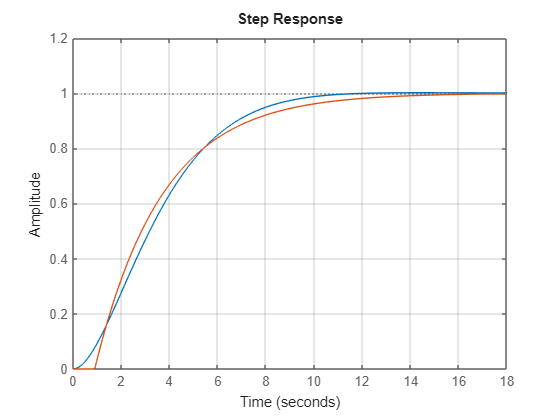

figure;
step(G);
grid on
hold on
num = 1;          
den = [2.8 1];      
ioDelay = 0.9;     
G_2 = tf(num, den, 'InputDelay', ioDelay);
step(G_2)

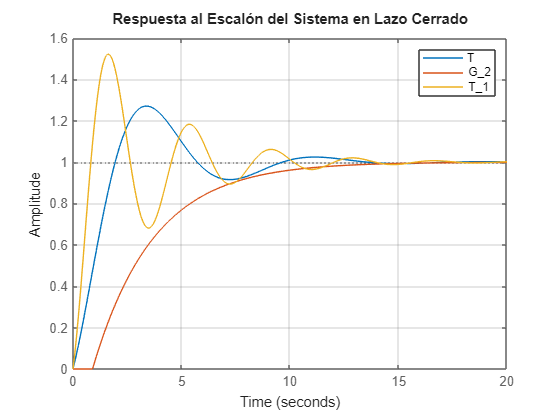



Kp = 3.73; % Ganancia proporcional (ajustar según el sistema)
Ti = 1.8; % Tiempo integral (ajustar según el sistema)
Td = 0.45; % Tiempo derivativo (ajustar según el sistema)

% Controlador PID
C = pid(Kp, Kp/Ti, Kp*Td);

T = feedback(C*G, 1);

figure;
step(T);
xlim([0, 20]);
title('Respuesta al Escalón del Sistema en Lazo Cerrado');
grid on;
hold on
step(G_2);

Kp = 13.2; % Ganancia proporcional (ajustar según el sistema)
Ti = 1; % Tiempo integral (ajustar según el sistema)
Td = 0.25; % Tiempo derivativo (ajustar según el sistema)

% Controlador PID
C = pid(Kp, Kp/Ti, Kp*Td);

T_1 = feedback(C*G, 1);
step(T_1);
legend()
hold off

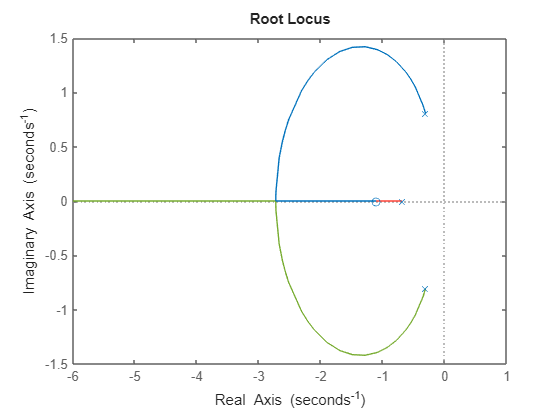


figure;
rlocus(T)